Importing the Image into MATLAB

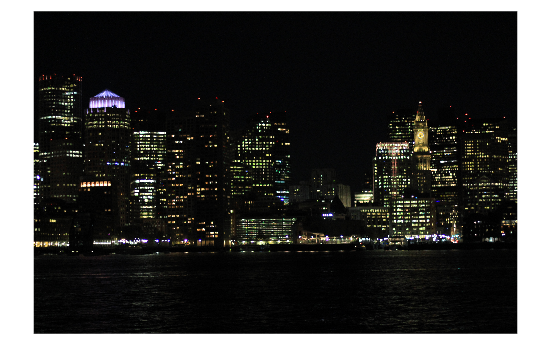

boston = imread("boston night.JPG");
imshow(boston)

Making it grayscale

GrayBoston = im2gray(boston)

GrayBoston = 3456×5184 uint8 matrix
   2   1   3   6   4   2   1   2   4   4   4   3   1   1   0   1   2   2   3   4   3   3   3   2   2   2   3   3   1   2   3   3   4   3   1   0   1   0   0   1   1   3   4   4   4   3   2   2   2   1
   2   2   5   7   4   1   1   2   3   3   3   3   2   1   0   0   1   1   2   2   2   4   5   4   2   2   2   1   0   0   3   4   3   2   0   0   0   0   0   1   3   4   4   4   3   2   1   2   3   3
   2   3   6   7   4   1   2   4   4   3   2   2   2   1   1   1   2   2   2   1   1   4   5   5   3   2   2   2   1   2   4   5   3   1   0   0   1   1   0   1   2   3   3   3   2   1   1   2   3   4
   3   4   6   6   3   1   4   6   5   3   2   2   2   2   1   1   4   4   3   1   1   3   5   4   3   1   1   2   2   3   4   5   3   2   1   1   2   2   0   0   1   2   1   1   1   1   0   2   2   3
   3   4   5   5   3   2   4   5   3   2   2   2   2   2   2   3   4   4   3   1   0   2   5   6   4   2   1   2   3   4   4   4   4   3   1   1   3   2   1   1

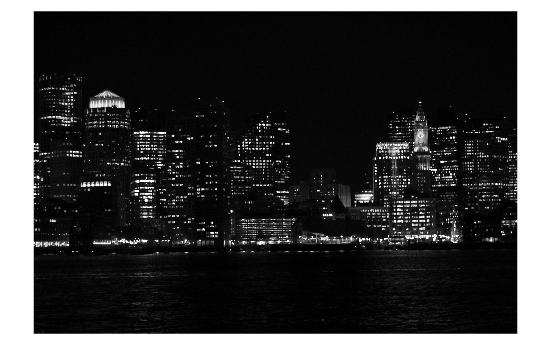

imshow(GrayBoston)

Adjusting Brightness using Gamma Correction

First of all we need to convert it into double format

DoubleBoston = im2double(GrayBoston)

DoubleBoston =     0.0078    0.0039    0.0118    0.0235    0.0157    0.0078    0.0039    0.0078    0.0157    0.0157    0.0157    0.0118    0.0039    0.0039         0    0.0039    0.0078    0.0078    0.0118    0.0157    0.0118    0.0118    0.0118    0.0078    0.0078    0.0078    0.0118    0.0118    0.0039    0.0078    0.0118    0.0118    0.0157    0.0118    0.0039         0    0.0039         0         0    0.0039    0.0039    0.0118    0.0157    0.0157    0.0157    0.0118    0.0078    0.0078    0.0078    0.0039
    0.0078    0.0078    0.0196    0.0275    0.0157    0.0039    0.0039    0.0078    0.0118    0.0118    0.0118    0.0118    0.0078    0.0039         0         0    0.0039    0.0039    0.0078    0.0078    0.0078    0.0157    0.0196    0.0157    0.0078    0.0078    0.0078    0.0039         0         0    0.0118    0.0157    0.0118    0.0078         0         0         0         0         0    0.0039    0.0118    0.0157    0.0157    0.0157    0.0118    0.0078    0.0039    0.0078    

Defining the Gamma Correction Value

Gamma = 1/2;

Applying the gamma correction to the image

brightenedBoston = DoubleBoston.^Gamma

brightenedBoston =     0.0886    0.0626    0.1085    0.1534    0.1252    0.0886    0.0626    0.0886    0.1252    0.1252    0.1252    0.1085    0.0626    0.0626         0    0.0626    0.0886    0.0886    0.1085    0.1252    0.1085    0.1085    0.1085    0.0886    0.0886    0.0886    0.1085    0.1085    0.0626    0.0886    0.1085    0.1085    0.1252    0.1085    0.0626         0    0.0626         0         0    0.0626    0.0626    0.1085    0.1252    0.1252    0.1252    0.1085    0.0886    0.0886    0.0886    0.0626
    0.0886    0.0886    0.1400    0.1657    0.1252    0.0626    0.0626    0.0886    0.1085    0.1085    0.1085    0.1085    0.0886    0.0626         0         0    0.0626    0.0626    0.0886    0.0886    0.0886    0.1252    0.1400    0.1252    0.0886    0.0886    0.0886    0.0626         0         0    0.1085    0.1252    0.1085    0.0886         0         0         0         0         0    0.0626    0.1085    0.1252    0.1252    0.1252    0.1085    0.0886    0.0626    0.0886

Adjusting Pixel values in range [0,1]

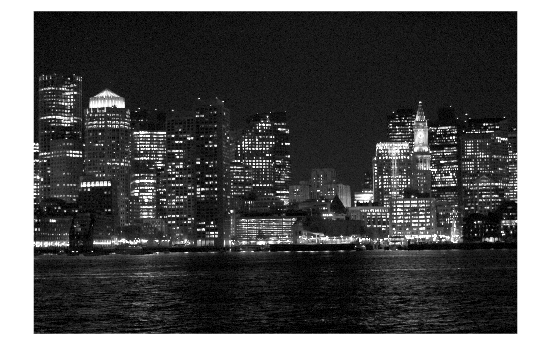

brightenedBoston = imadjust(brightenedBoston);
imshow(brightenedBoston);

Rotating 1 Degree

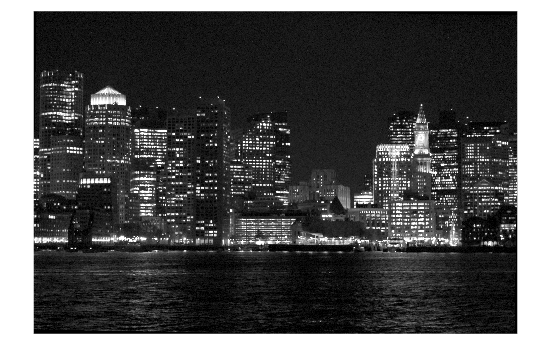

RotatedBrightenedBoston = imrotate(brightenedBoston,-1,"crop");
imshow(RotatedBrightenedBoston)

Converting back to uint8

RotatedBrightenedBoston = im2uint8(RotatedBrightenedBoston)

RotatedBrightenedBoston = 3456×5184 uint8 matrix
    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0   23   19   19   19   14    8    8    8    0    0    0    0    0   14   14    8   14    8    8   19
    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0   23   23   23   14    0    0    8    8    0    0    0    8    8    0    8   14   19    8    8   14
    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0   27   27   27   19    8    8    8    8    8    0    8   19   14    0    0   23   19    8    0    8
    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0   23   23   27   23   14    8    8   14   14   

Comparing old and new

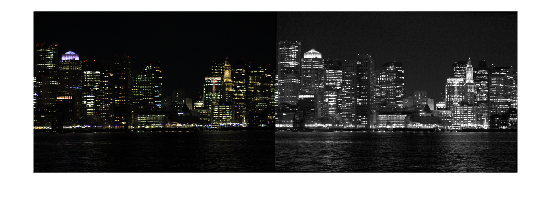

montage({boston,RotatedBrightenedBoston});

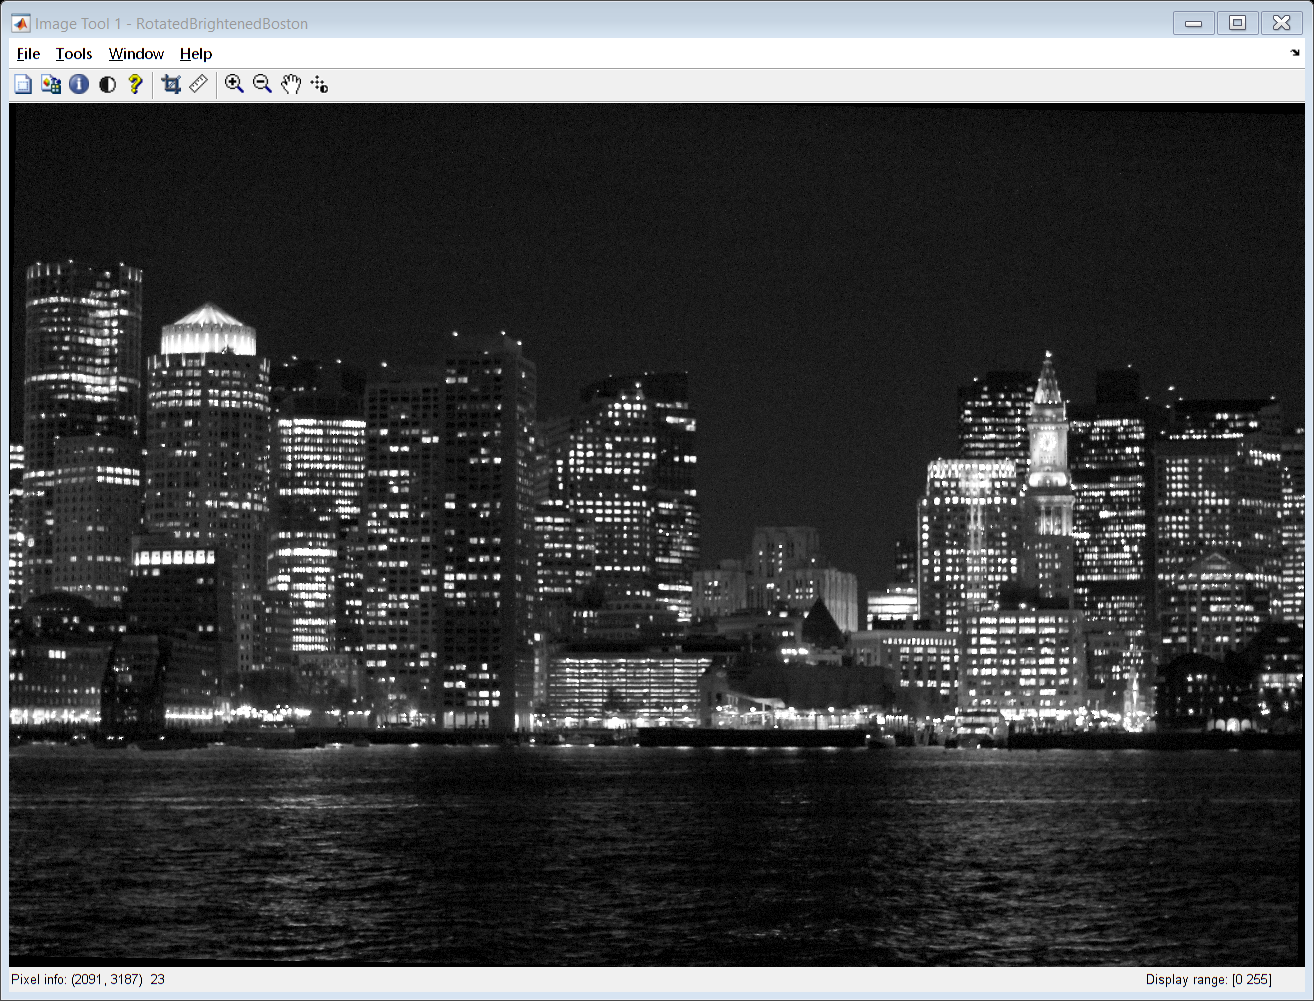

imtool(RotatedBrightenedBoston)